# Part 1 OFDM signal generation and reception

## Waveform generation for one OFDM symbol

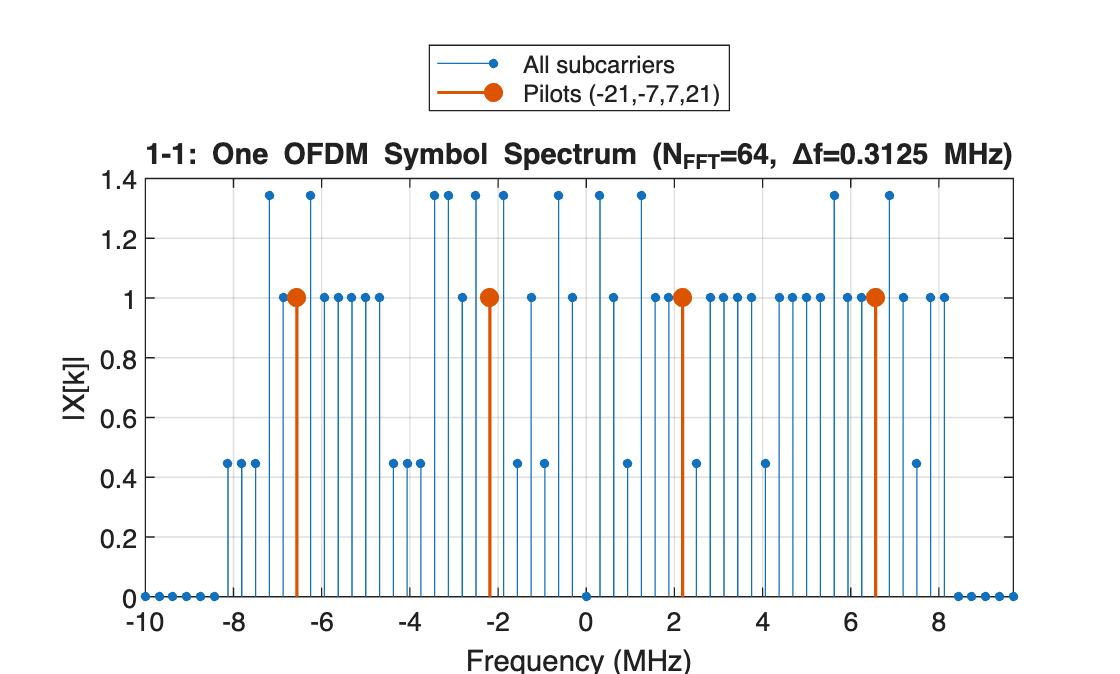

%1
% Wi-Fi OFDM parameters
Nfft = 64;                  % FFT size
Fs   = 20e6;                % Sampling rate (Hz)
df   = Fs/Nfft;             % Subcarrier spacing (Hz) = 312.5 kHz
k_active = [-26:-1 1:26];   % Active subcarriers (DC removed)
pilot_idx_k = [-21 -7 7 21];% Pilot tone indices (802.11a/g)

% llocate frequency-domain vector X 
X = zeros(1, Nfft);         % Frequency-domain

% Map k -> MATLAB index when DC is centered
k_all = (-Nfft/2):(Nfft/2-1);              % [-32..31]
toIdx = @(k) find(k_all==k);               % helper to find position

% Generate pilots (BPSK)
pilots = sign(randn(1, numel(pilot_idx_k)));  % ±1 BPSK
for i = 1:numel(pilot_idx_k)
    X(toIdx(pilot_idx_k(i))) = pilots(i);
end

% Generate data (16-QAM, unit average power)
M = 16;
data_k = setdiff(k_active, pilot_idx_k);      % data subcarriers (48 tones)
num_data = numel(data_k);
data_syms = qammod(randi([0 M-1], num_data, 1), M, 'gray', 'UnitAveragePower', true);

for i = 1:num_data
    X(toIdx(data_k(i))) = data_syms(i);
end

% Build frequency axis in MHz (DC at center)
f_MHz = k_all * (df/1e6);  % [-32..31] * 0.3125 MHz

% Plot magnitude spectrum
figure; hold on; box on; grid on;
stem(f_MHz, abs(X), 'filled', 'MarkerSize', 3);          % all tones
% Overlay pilots in a different color & larger markers
pilot_pos = arrayfun(toIdx, pilot_idx_k);
stem(f_MHz(pilot_pos), abs(X(pilot_pos)), 'filled', 'LineWidth', 1.2, 'MarkerSize', 6);

xlabel('Frequency (MHz)'); ylabel('|X[k]|');
title(sprintf('1-1: One OFDM Symbol Spectrum (N_{FFT}=%d, \\Deltaf=%.4f MHz)', Nfft, df/1e6));
legend('All subcarriers','Pilots (-21,-7,7,21)','Location','northoutside');
xlim([min(f_MHz) max(f_MHz)]);

%2
fprintf('[1-2] Subcarrier spacing Δf = %.4f MHz\n', df/1e6);

[1-2] Subcarrier spacing Δf = 0.3125 MHz


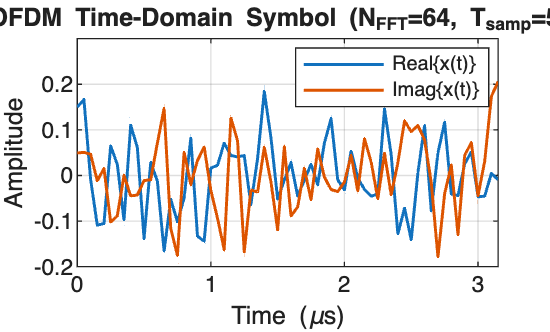

%3
X_ifft = ifftshift(X);          % from DC-centered -> natural order (k=0 at index 1)
x_time = ifft(X_ifft, Nfft);    % one OFDM symbol in time domain (no CP)
x_time = x_time(:);
t_us = (0:Nfft-1)/Fs * 1e6;     % 64 points, difference = 1/Fs，unit to microseconds

% plot the real and imaginary part
figure; 
plot(t_us, real(x_time), 'LineWidth', 1.1); hold on; grid on; box on;
plot(t_us, imag(x_time), 'LineWidth', 1.1);
xlabel('Time (\mus)'); ylabel('Amplitude');
title(sprintf('1-3: OFDM Time-Domain Symbol (N_{FFT}=%d, T_{samp}=%.1f ns)', ...
              Nfft, 1e9/Fs));
legend('Real\{x(t)\}','Imag\{x(t)\}','Location','best');

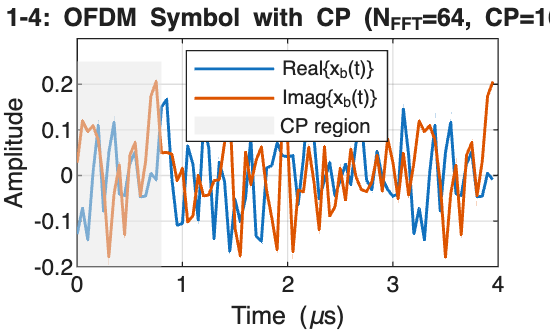

%4
Lcp = 16;                        % cyclic prefix length (samples)
cp   = x_time(end-Lcp+1:end);    % copy last Lcp samples
x_cp = [cp; x_time(:)];          % signal (b): CP + useful symbol

% time axis in microseconds
t_b_us = (0:length(x_cp)-1)/Fs * 1e6;

% figure: real/imag with CP region marked
figure; hold on; grid on; box on;
plot(t_b_us, real(x_cp), 'LineWidth', 1.1);
plot(t_b_us, imag(x_cp), 'LineWidth', 1.1);

% Mark CP region [0, Lcp/Fs]
yl = ylim;
cp_end_us = (Lcp)/Fs * 1e6;
patch([0 cp_end_us cp_end_us 0], [yl(1) yl(1) yl(2) yl(2)], [0.9 0.9 0.9], ...
      'EdgeColor','none','FaceAlpha',0.5);

xlabel('Time (\mus)'); ylabel('Amplitude');
title(sprintf('1-4: OFDM Symbol with CP (N_{FFT}=%d, CP=%d)', Nfft, Lcp));
legend('Real\{x_b(t)\}','Imag\{x_b(t)\}','CP region','Location','best');

%5
Tu   = Nfft/Fs;          % useful symbol duration (s)
Tcp  = Lcp/Fs;           % CP duration (s)
Ts   = (Nfft+Lcp)/Fs;    % total OFDM symbol duration (s)

fprintf('[1-5] Useful symbol (no CP)  = %.1f us\n', 1e6*Tu);

[1-5] Useful symbol (no CP)  = 3.2 us


fprintf('[1-5] Cyclic prefix (CP)     = %.1f us\n', 1e6*Tcp);

[1-5] Cyclic prefix (CP)     = 0.8 us


fprintf('[1-5] Total (with CP)        = %.1f us\n', 1e6*Ts);

[1-5] Total (with CP)        = 4.0 us


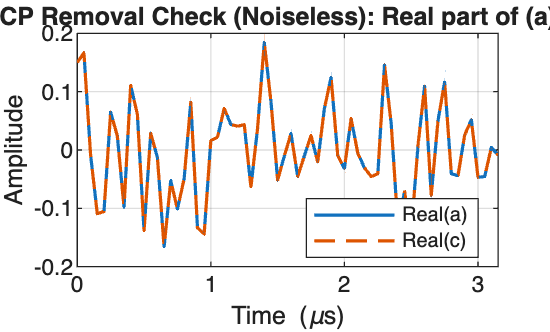

%6
y_cp = x_cp;                              % noiseless channel
% remove cp to obtain (c)
x_c = y_cp(Lcp+1 : Lcp+Nfft);

% time axis, same with (a)，0 ~ 3.2 us
t_a_us = (0:Nfft-1)/Fs * 1e6;
t_c_us = t_a_us;

%plot the real part of (a) and (c), should be the same 
figure; hold on; grid on; box on;
plot(t_a_us, real(x_time), 'LineWidth', 1.2);       % signal (a) without CP
plot(t_c_us, real(x_c),   '--', 'LineWidth', 1.2);  % signal (c) after CP removal
xlabel('Time (\mus)'); ylabel('Amplitude');
title('1-6: CP Removal Check (Noiseless): Real part of (a) vs (c)');
legend('Real{(a)}','Real{(c)}','Location','best');

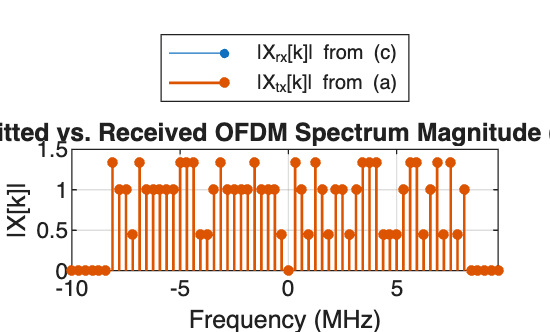

%7
% do the fft to (c) and center it
X_rx_nat   = fft(x_c, Nfft);
X_rx_shift = fftshift(X_rx_nat);

% freq axis: MHz, DC in the center
k_all = (-Nfft/2):(Nfft/2-1);
f_MHz = (Fs/Nfft)/1e6 * k_all;        % Δf = Fs/Nfft，unit to MHz

% 3) plot the OFDM symbol
figure; hold on; grid on; box on;
stem(f_MHz, abs(X_rx_shift), 'filled', 'MarkerSize', 3);             % receive
stem(f_MHz, abs(X),          'filled', 'LineWidth',1.0, 'MarkerSize', 3); % transmit
xlabel('Frequency (MHz)'); ylabel('|X[k]|');
title('1-7: Transmitted vs. Received OFDM Spectrum Magnitude (DC-centered)');
legend('|X_{rx}[k]| from (c)','|X_{tx}[k]| from (a)','Location','northoutside');
xlim([min(f_MHz) max(f_MHz)]);

fprintf('[1-7] The trasmitted and received OFDM symbols are identical.');

[1-7] The trasmitted and received OFDM symbols are identical.

## Simulate OFDM transmissions for different SNRs

%8
rng(7);
Nsym = 1000;
papr_lin   = zeros(Nsym,1);
papr_dB    = zeros(Nsym,1);
peak_pwr   = zeros(Nsym,1);
avg_pwr    = zeros(Nsym,1);
tx_all = [];

for n = 1:Nsym
    % build freq X（DC centered）
    Xn = zeros(1, Nfft);

    % random pilots（BPSK ±1）
    pilots = sign(randn(1, numel(pilot_idx_k)));
    for i = 1:numel(pilot_idx_k)
        Xn(toIdx(pilot_idx_k(i))) = pilots(i);
    end

    % random 16-QAM（average power =1）
    data_syms = qammod(randi([0 M-1], numel(data_k), 1), M, 'gray', 'UnitAveragePower', true);
    for i = 1:numel(data_k)
        Xn(toIdx(data_k(i))) = data_syms(i);
    end

    % IFFT, no cp included
    x_time_n = ifft(ifftshift(Xn), Nfft).';
    % --- power and 與 PAPR
    p = abs(x_time_n).^2;
    peak_pwr(n) = max(p);
    avg_pwr(n)  = mean(p);
    papr_lin(n) = peak_pwr(n) / avg_pwr(n);
    papr_dB(n)  = 10*log10(papr_lin(n));
    tx_all = [tx_all; x_time_n];
end

% peak, average, and PAPR
P_overall_peak = max(abs(tx_all).^2);
P_overall_avg  = mean(abs(tx_all).^2);
PAPR_overall_lin = P_overall_peak / P_overall_avg;
PAPR_overall_dB  = 10*log10(PAPR_overall_lin);

fprintf('\n[1-8] Results over %d OFDM symbols:\n', Nsym);


[1-8] Results over 1000 OFDM symbols:


fprintf('  Overall peak power      = %.4f\n', P_overall_peak);

  Overall peak power      = 0.1355


fprintf('  Overall average power   = %.4f\n', P_overall_avg);

  Overall average power   = 0.0127


fprintf('  Overall PAPR            = %.2f (%.2f dB)\n', PAPR_overall_lin, PAPR_overall_dB);

  Overall PAPR            = 10.64 (10.27 dB)


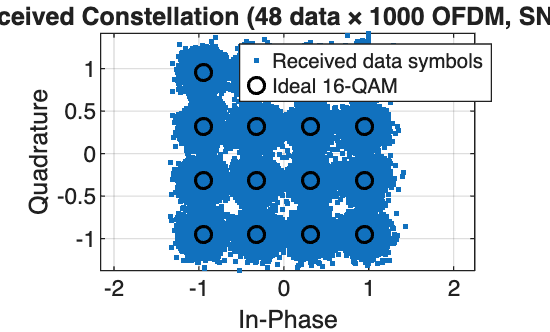

%9
rng(9);
SNR_dB = 15;
rx_data_all = complex([],[]);

idx_active = arrayfun(toIdx, k_active);     % 52 tones (含 pilot)
idx_data   = arrayfun(toIdx, data_k);       % 48 data tones

for n = 1:Nsym
    % init freq Xn (DC-centered), put pilots + data every symbol
    Xn = zeros(1, Nfft);

    % pilots: BPSK ±1
    pilots = sign(randn(1, numel(pilot_idx_k)));
    for i = 1:numel(pilot_idx_k)
        Xn(toIdx(pilot_idx_k(i))) = pilots(i);
    end

    % data: 16-QAM (unit avg power)
    data_syms = qammod(randi([0 M-1], numel(data_k), 1), M, ...
                       'gray', 'UnitAveragePower', true);
    for i = 1:numel(data_k)
        Xn(toIdx(data_k(i))) = data_syms(i);
    end

    % time-domain (a), add CP (b)
    x_time_n = ifft(ifftshift(Xn), Nfft).';               % 64x1
    xcp_n    = [x_time_n(end-Lcp+1:end); x_time_n];       % 80x1

    % AWGN channel (SNR ref = with-CP power)
    Ps       = mean(abs(xcp_n).^2);
    SNR_lin  = 10^(SNR_dB/10);
    noiseVar = Ps / SNR_lin;
    w        = sqrt(noiseVar/2) * (randn(size(xcp_n)) + 1j*randn(size(xcp_n)));
    ycp_n    = xcp_n + w;

    % remove CP -> (c), FFT -> DC-centered
    yc_n      = ycp_n(Lcp+1 : Lcp+Nfft);
    Xrx_shift = fftshift(fft(yc_n, Nfft));

    % collect received data subcarriers
    rx_data_all = [rx_data_all; Xrx_shift(idx_data)]; %#ok<AGROW>
end

% plot constellation
ideal_const = qammod((0:M-1).', M, 'gray', 'UnitAveragePower', true);
figure; hold on; grid on; box on;
plot(real(rx_data_all), imag(rx_data_all), '.', 'MarkerSize', 6);
plot(real(ideal_const), imag(ideal_const), 'ok', 'LineWidth', 1.2, 'MarkerSize', 6);
axis equal; xlabel('In-Phase'); ylabel('Quadrature');
title(sprintf('1-9: Received Constellation (48 data × %d OFDM, SNR=%d dB)', Nsym, SNR_dB));
legend('Received data symbols','Ideal 16-QAM','Location','best');

%10
rng(10);
snr_freq_lin  = zeros(Nsym,1);

for n = 1:Nsym
    Xn = zeros(1, Nfft);
    pilots = sign(randn(1, numel(pilot_idx_k)));
    for i = 1:numel(pilot_idx_k)
        Xn(toIdx(pilot_idx_k(i))) = pilots(i);
    end
    data_syms = qammod(randi([0 M-1], numel(data_k), 1), M, ...
                       'gray', 'UnitAveragePower', true);
    for i = 1:numel(data_k)
        Xn(toIdx(data_k(i))) = data_syms(i);
    end

    % tx (a)->(b), AWGN
    x_time_n = ifft(ifftshift(Xn), Nfft).';
    xcp_n    = [x_time_n(end-Lcp+1:end); x_time_n];

    Ps       = mean(abs(xcp_n).^2);
    SNR_lin  = 10^(SNR_dB/10);
    noiseVar = Ps / SNR_lin;
    w        = sqrt(noiseVar/2) * (randn(size(xcp_n)) + 1j*randn(size(xcp_n)));
    ycp_n    = xcp_n + w;

    % rx -> (c) -> FFT
    yc_n      = ycp_n(Lcp+1 : Lcp+Nfft);
    Xrx_shift = fftshift(fft(yc_n, Nfft));   % 64x1
    Xtx_shift = Xn(:);                       % 64x1 (make column)

    % SNR over 52 active tones
    Es = mean(abs(Xtx_shift(idx_active)).^2);                             % signal power
    En = mean(abs(Xrx_shift(idx_active) - Xtx_shift(idx_active)).^2);     % noise power
    snr_freq_lin(n) = Es / En * (52/64);
end

mean_snr_freq_dB = 10*log10(mean(snr_freq_lin));
fprintf('\n[1-10] Measured SNR :  %.2f dB (target 15 dB)\n', mean_snr_freq_dB);


[1-10] Measured SNR :  15.07 dB (target 15 dB)


%11
rng(11);
SNR_dB_list = [0 5 10 15];

bits_per_sym = log2(M);                     % 16-QAM -> 4 bits/symbol
BER = zeros(numel(SNR_dB_list), 1);

for si = 1:numel(SNR_dB_list)
    SNR_dB  = SNR_dB_list(si);
    SNR_lin = 10^(SNR_dB/10);
    bit_err = 0;
    bit_tot = 0;

    for n = 1:Nsym
        % data: 16-QAM
        tx_sym_idx = randi([0 M-1], numel(data_k), 1); % 48×1（整數標籤）
        data_syms  = qammod(tx_sym_idx, M, 'gray', 'UnitAveragePower', true);
        for i = 1:numel(data_k)
            Xn(toIdx(data_k(i))) = data_syms(i);
        end

        %IFFT -> (a) add CP and transmit
        x_time_n = ifft(ifftshift(Xn), Nfft).';
        xcp_n    = [x_time_n(end-Lcp+1:end); x_time_n];

        % AWGN channel
        Ps       = mean(abs(xcp_n).^2);
        noiseVar = Ps / SNR_lin;
        w        = sqrt(noiseVar/2) * (randn(size(xcp_n)) + 1j*randn(size(xcp_n)));
        ycp_n    = xcp_n + w;

        % remove CP -> (c), FFT to freq domain
        yc_n      = ycp_n(Lcp+1 : Lcp+Nfft);
        Xrx_shift = fftshift(fft(yc_n, Nfft));

        % get data and demod
        rx_data = Xrx_shift(idx_data);                         % 48×1
        rx_sym_idx = qamdemod(rx_data, M, 'gray','UnitAveragePower', true);      % 48×1 

        % compute the bit error
        tx_bits = de2bi(tx_sym_idx, bits_per_sym, 'left-msb'); % 48×4
        rx_bits = de2bi(rx_sym_idx, bits_per_sym, 'left-msb'); % 48×4
        bit_err = bit_err + sum(tx_bits(:) ~= rx_bits(:));
        bit_tot = bit_tot + numel(tx_bits);
    end

    BER(si) = bit_err / bit_tot;
    fprintf('[1-11] SNR=%2d dB: BER = %.4g  (bit_err=%d / %d)\n', ...
            SNR_dB, BER(si), bit_err, bit_tot);
end

[1-11] SNR= 0 dB: BER = 0.2667  (bit_err=51207 / 192000)
[1-11] SNR= 5 dB: BER = 0.1418  (bit_err=27219 / 192000)
[1-11] SNR=10 dB: BER = 0.04448  (bit_err=8540 / 192000)
[1-11] SNR=15 dB: BER = 0.002193  (bit_err=421 / 192000)


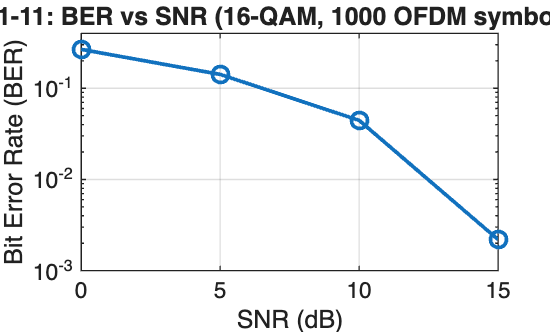

% plot BER vs SNR
figure; grid on; box on; hold on;
semilogy(SNR_dB_list, BER, 'o-', 'LineWidth', 1.4, 'MarkerSize', 6);
xlabel('SNR (dB)'); ylabel('Bit Error Rate (BER)');
title(sprintf('1-11: BER vs SNR (16-QAM, %d OFDM symbols)', Nsym));
xlim([min(SNR_dB_list) max(SNR_dB_list)]);
ylim([1e-3 0.4]);
ax = gca;
ax.YScale = 'log';                 % force log scale
ax.YTick  = 10.^(-3:-1);           % [1e-4 1e-3 1e-2 1e-1]

ax.YMinorGrid = 'off';

As the SNR increases from 0 → 15 dB, the BER drops quickly from about 0.27 down to nearly 0.01.

This means that when the signal becomes stronger compared to noise, the receiver makes far fewer bit errors.

# Part 2 STS& LTS for frame synchronization and equalization

## STS & LTS generation and frame synchronization

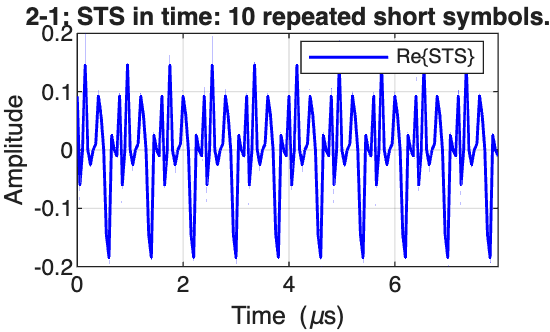

%1
sts_pos  = [-24 -20 -16 -12 -8 -4 4 8 12 16 20 24];
sts_vals = [1+1j,  1+1j, -1-1j, -1-1j,  1+1j,  1+1j,-1-1j,  1+1j, -1+1j,  1-1j,  1+1j,  1+1j ].';

alpha = sqrt(13/6);
X_sts_shift = zeros(Nfft,1);
X_sts_shift(arrayfun(toIdx, sts_pos)) = alpha * sts_vals;

% IFFT to get 64 point on time domain, then pick any conti 16 points as symbpl, ten times.
x_sts64 = ifft(ifftshift(X_sts_shift), Nfft).';  % 64×1
x_sts64 = x_sts64(:);
short16 = x_sts64(1:16);                         % 16×1（0.05*16 = 0.8 µs）
sts_td  = repmat(short16, 10, 1);                % 160×1（10 short, 8 µs）

% plot the time domain, real part
t_sts_us = (0:length(sts_td)-1)/Fs * 1e6;
figure; hold on; grid on; box on;
plot(t_sts_us, real(sts_td), 'b-','LineWidth', 1.1);
xlabel('Time (\mus)'); ylabel('Amplitude');
title('2-1: STS in time: 10 repeated short symbols.');
xlim([0 t_sts_us(end)]);
legend('Re\{STS\}','Location','best');

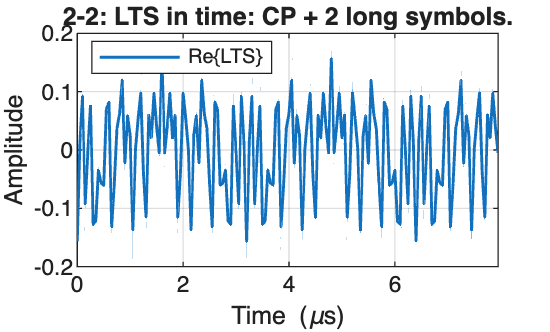

%2
k_lts = [-26:-1 1:26];
X_lts_shift = zeros(Nfft,1);
L_vals = [1,  1, -1, -1,  1,  1, -1,  1, -1,  1,  1,  1,  1,  1,  1, -1, -1,  1,  1, -1,  1, -1,  1,  1,  1,  1, ...
  1, -1, -1,  1,  1, -1,  1, -1,  1, -1, -1, -1, -1, -1,  1,  1, -1, -1,  1, -1,  1, -1,  1,  1,  1,  1 ].';
X_lts_shift(arrayfun(toIdx, k_lts)) = L_vals;
x_lts64 = ifft(ifftshift(X_lts_shift), Nfft).';
x_lts64 = x_lts64(:);

% = CP(32) + LTS(64) + LTS(64) = total 160 points*0.05 = 8 µs
cp_lts = x_lts64(end-32+1:end);                   % 32×1
lts_td  = [cp_lts; x_lts64; x_lts64];             % 160×1

% plot the time domain, real part
t_lts_us = (0:length(lts_td)-1)/Fs * 1e6;
figure; hold on; grid on; box on;
plot(t_lts_us, real(lts_td), 'LineWidth', 1.1);
xlabel('Time (\mus)'); ylabel('Amplitude');
title('2-2: LTS in time: CP + 2 long symbols.');
xlim([0 t_lts_us(end)]);
legend('Re\{LTS\}','Location','best');

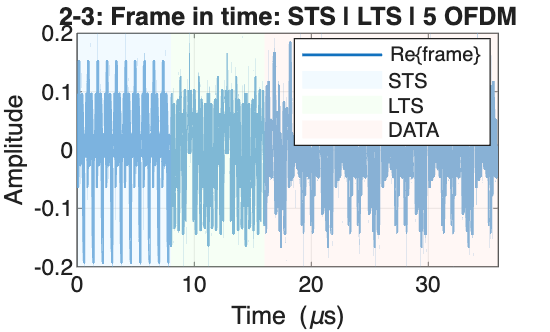

%3
rms_ref = rms(x_cp);
sts_td_aligned = sts_td * (rms_ref / rms(sts_td));
lts_td_aligned = lts_td * (rms_ref / rms(lts_td));
% data: use the OFDM in part 1, copy five times
data5_td = repmat(x_cp, 5, 1);                 % 5×80 = 400×1
% combine into one frame：160 + 160 + 400 = 720 samples
frame_td = [sts_td_aligned; lts_td_aligned; data5_td];   % 720×1
t_us = (0:length(frame_td)-1)/Fs * 1e6;                  % μs
% plot and mark the data portion
figure; hold on; grid on; box on;
plot(t_us, real(frame_td), 'LineWidth', 1.05);
xlabel('Time (\mus)'); ylabel('Amplitude');
title('2-3: Frame in time: STS | LTS | 5 OFDM');

n_sts=160; n_lts=160; n_data=5*(Nfft+Lcp);   % =400
yl = ylim;
patch([0, n_sts/Fs*1e6, n_sts/Fs*1e6, 0], yl([1 1 2 2]), [0.90 0.96 1.00], ...
      'EdgeColor','none','FaceAlpha',0.5);
patch([n_sts/Fs*1e6, (n_sts+n_lts)/Fs*1e6, (n_sts+n_lts)/Fs*1e6, n_sts/Fs*1e6], ...
      yl([1 1 2 2]), [0.93 1.00 0.92], 'EdgeColor','none','FaceAlpha',0.5);
patch([(n_sts+n_lts)/Fs*1e6, (n_sts+n_lts+n_data)/Fs*1e6, ...
       (n_sts+n_lts+n_data)/Fs*1e6, (n_sts+n_lts)/Fs*1e6], ...
      yl([1 1 2 2]), [1.00 0.94 0.92], 'EdgeColor','none','FaceAlpha',0.5);
legend('Re\{frame\}','STS','LTS','DATA','Location','best');
xlim([0 t_us(end)]);

%4
function sync = sync_by_sts(rx, sts_templ, Nfft, Lcp, nLTS)
    rx = rx(:);
    L  = numel(sts_templ);
    h  = conj(flipud(sts_templ(:)/norm(sts_templ)));   % unit energy template
    z  = filter(h, 1, rx);                              % match filter output
    e  = filter(ones(L,1), 1, abs(rx).^2);              % window energy, length L
    metric = abs(z).^2 ./ (e + eps);                    % normalize

    % peak at the end of STS
    [~, rel] = max(metric(L:end));
    idx_peak = rel + L - 1;
    idx_sts_start = max(1, idx_peak - L + 1);          % STS start
    idx_lts_start = idx_sts_start + nLTS;               % LTS start

    % 5 OFDM（with-CP）start
    sym_span = Nfft + Lcp;                              % 80
    idx_data_cp_start = idx_lts_start + nLTS + (0:4).' * sym_span;

    % package
    sync.idx_sts_start     = idx_sts_start;
    sync.idx_lts_start     = idx_lts_start;
    sync.idx_data_cp_start = idx_data_cp_start;
    sync.metric            = metric;
end
nLTS = 160;  % LTS length（CP32+64+64）
sync = sync_by_sts(frame_td, sts_td_aligned, Nfft, Lcp, nLTS);

fprintf('[2-4] STS start @ n=%d, LTS start @ n=%d\n', sync.idx_sts_start, sync.idx_lts_start);

[2-4] STS start @ n=1, LTS start @ n=161


fprintf('[2-4] OFDM starts: %s\n', mat2str(sync.idx_data_cp_start.'));

[2-4] OFDM starts: [321 401 481 561 641]


%algorithm explain:
% SYNC_BY_STS: match filter synchronization（using for zero padding, noise, and determine the start of OFDM）
% Input
%   rx         : column vector, the recieved time domain signal（may include noise and zeros）
%   sts_templ  : 160×1 STS template
%   Nfft, Lcp  : 64, 16 in this case
%   nLTS       : LTS length, 160 in this case
% Output (struct)
%   idx_sts_start      : STS start symbol
%   idx_lts_start      : LTS start symbol
%   idx_data_cp_start  : 5 ofdm symbol start(with CP)
%   metric             : normalized match milter, |corr|^2 / (window energy)
%
% algorithm：
% 1) use the whole 160 points of STS as template of match filter：h = conj(flipud(sts_templ/norm))
% 2) compute normalization for the scaling of amplitude or noise
%         metric(n) = |(rx * h)(n)|^2 / ( sum_{n-L+1..n} |rx|^2 + eps )
% 3) take the peak of metric idx_peak，and find the start of STS：
%         idx_sts_start = idx_peak - L+1
%    then LTS start = idx_sts_start + 160
%         data with-CP start = LTS start + 160 + m*(Nfft+Lcp), m=0..4

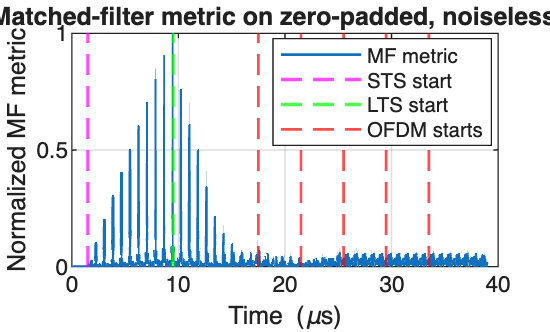

%5
% Zero-padded
padN = 30;
rx_zeropad = [zeros(padN,1); frame_td; zeros(padN,1)];
sync5 = sync_by_sts(rx_zeropad, sts_td_aligned, Nfft, Lcp, 160);

% plot the match filter
t_metric_us = (0:numel(sync5.metric)-1)/Fs * 1e6;

figure; hold on; grid on; box on;
plot(t_metric_us, sync5.metric, 'LineWidth', 1.1);
xlabel('Time (\mus)'); ylabel('Normalized MF metric');
title('2-5: Matched-filter metric on zero-padded, noiseless frame');

% mark the start of STS, LTS, and 5 OFDM
yl = ylim;
xline((sync5.idx_sts_start-1)/Fs*1e6,  '--m', 'LineWidth', 1.3);
xline((sync5.idx_lts_start-1)/Fs*1e6,  '--g', 'LineWidth', 1.3);
for k = 1:numel(sync5.idx_data_cp_start)
    xline((sync5.idx_data_cp_start(k)-1)/Fs*1e6, '--r', 'LineWidth', 1.0);
end
legend('MF metric','STS start','LTS start','OFDM starts','Location','best');


% verification
idx_expected_sts = padN + 1;
hit_ok = (sync5.idx_sts_start == idx_expected_sts);

fprintf('[2-5] Detected STS start = %d (expected %d) → %s\n', sync5.idx_sts_start, idx_expected_sts, string(hit_ok));

[2-5] Detected STS start = 31 (expected 31) → true


fprintf('[2-5] Detected LTS start = %d\n', sync5.idx_lts_start);

[2-5] Detected LTS start = 191


fprintf('[2-5] Detected OFDM = %s\n', mat2str(sync5.idx_data_cp_start.'));

[2-5] Detected OFDM = [351 431 511 591 671]


In this case where 30 zero padding at the beginning and the end without noise, the detected start of STS is n = 31, same as the expected value (1+30).

The start of LTS and each OFDM is also correct, and can be verified easily.

%6
sync6 = sync_by_sts(frame_td, sts_td_aligned, Nfft, Lcp, 160);
tx_sym_idx_ref = qamdemod(X(idx_data).', M, 'gray','UnitAveragePower', true); % 48×1
tx_bits_ref = de2bi(tx_sym_idx_ref, log2(M), 'left-msb'); % 48×4

% 3) deal with 5 OFDM symbol
bit_err_total = 0; 
bit_tot_total = 0;

for m = 1:numel(sync6.idx_data_cp_start)
    n0 = sync6.idx_data_cp_start(m)+ Lcp;
    seg = frame_td(n0 : n0+Nfft-1);                  % 64×1
    Xrx_shift = fftshift(fft(seg, Nfft));            % 64×1

    % get data and demod
    rx_data = Xrx_shift(idx_data);
    rx_sym_idx = qamdemod(rx_data, M, 'gray', 'UnitAveragePower', true); % 48×1
    rx_bits = de2bi(rx_sym_idx, log2(M), 'left-msb');                    % 48×4

    % acccumulated BER
    bit_err_total = bit_err_total + sum(rx_bits(:) ~= tx_bits_ref(:));
    bit_tot_total = bit_tot_total + numel(tx_bits_ref);
end

BER_6 = bit_err_total / bit_tot_total;
fprintf('[2-6] Total bit errors over 5 OFDM symbols = %d / %d  → BER = %.3g\n', ...
        bit_err_total, bit_tot_total, BER_6);

[2-6] Total bit errors over 5 OFDM symbols = 0 / 960  → BER = 0


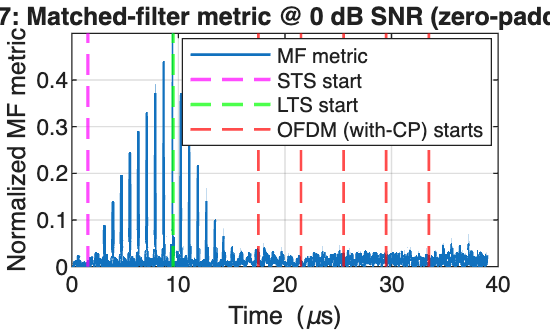

%7
%zero-padding and add AWGN noise
Ps_frame = mean(abs(frame_td).^2);
SNR_dB_2 = 0;
SNR_lin_2 = 10^(SNR_dB_2/10);
noiseVar = Ps_frame / SNR_lin_2;% 0 dB → noise power = signal power

w = sqrt(noiseVar/2) * (randn(size(rx_zeropad)) + 1j*randn(size(rx_zeropad)));
rx_noisy = rx_zeropad + w;

sync7 = sync_by_sts(rx_noisy, sts_td_aligned, Nfft, Lcp, 160);
t_metric_us = (0:numel(sync7.metric)-1)/Fs * 1e6;

%plot
figure; hold on; grid on; box on;
plot(t_metric_us, sync7.metric, 'LineWidth', 1.1);
xlabel('Time (\mus)'); ylabel('Normalized MF metric');
title('2-7: Matched-filter metric @ 0 dB SNR (zero-padded)');

yl = ylim;
xline((sync7.idx_sts_start-1)/Fs*1e6,  '--m', 'LineWidth', 1.3); % STS start
xline((sync7.idx_lts_start-1)/Fs*1e6,  '--g', 'LineWidth', 1.3); % LTS start
for k = 1:numel(sync7.idx_data_cp_start)
    xline((sync7.idx_data_cp_start(k)-1)/Fs*1e6, '--r', 'LineWidth', 1.0);
end
legend('MF metric','STS start','LTS start','OFDM (with-CP) starts','Location','best');


% check the correctness
idx_expected_sts = padN + 1;
hit_ok = (sync7.idx_sts_start == idx_expected_sts);
fprintf('[2-7] Detected STS start = %d (expected %d) → %s\n', ...
        sync7.idx_sts_start, idx_expected_sts, string(hit_ok));

[2-7] Detected STS start = 31 (expected 31) → true


As explained in (5), it is correct that STS starts at n = 31

%8
function sync = sync_by_lts(rx, lts160, Nfft, Lcp)
    rx = rx(:);
    lts160 = lts160(:);                 % expect length 160 = 32+64+64
    L = numel(lts160);

    % Matched filter with FULL LTS block (CP+LTS1+LTS2)
    templ  = lts160 / norm(lts160);     % unit-energy template
    h      = conj(flipud(templ));
    z      = filter(h, 1, rx);
    % 你也寫了能量窗 e，但這裡 metric 用 abs(z).^2 就夠了
    metric = abs(z).^2;

    % Peak at template END → CP start = peak - L + 1
    [~, rel] = max(metric(L:end));
    idx_peak = rel + L - 1;                      % aligns at end of LTS block
    idx_lts_cp_start   = idx_peak - L + 1;       % ★ 刪掉強制 >=161 的那行 ★
    idx_lts_sym1_start = idx_lts_cp_start + 32;  % first 64-sample LTS (no CP)

    % 5 OFDM (with-CP) starts
    span = Nfft + Lcp;                            % 80
    idx_data_cp_start = idx_lts_cp_start + 160 + (0:4).' * span;

    % package
    sync.idx_lts_cp_start   = idx_lts_cp_start;
    sync.idx_lts_sym1_start = idx_lts_sym1_start;
    sync.idx_data_cp_start  = idx_data_cp_start;
    sync.metric             = metric;
end

syncL = sync_by_lts(frame_td, lts_td, Nfft, Lcp);
fprintf('[2-8] LTS CP start n=%d, sym1 start (no CP) n=%d\n', ...
        syncL.idx_lts_cp_start, syncL.idx_lts_sym1_start);

[2-8] LTS CP start n=161, sym1 start (no CP) n=193


fprintf('[2-8] OFDM starts: %s\n', mat2str(syncL.idx_data_cp_start.'));

[2-8] OFDM starts: [321 401 481 561 641]


%algorithm explain:
%SYNC_BY_LTS
% Input/Output: similar to %4
% algorithm：
% 1) template = [lts64; lts64]，length 128.
% 2) match filter z = filter(conj(flipud(templ)), 1, rx).
% 3) normalize metric(n) = |z(n)|^2 / (sum_{n-L+1..n} |rx|^2 + eps)，L=128.
%    this makes the noise and zero padding more steady.
% 4) take the peak of metric as idx_peak（at the end of second LTS）.
%    → first LTS start = idx_peak - (2*64) + 1
%    → LTS CP start = above - 32
% 5) use the length of LTS 160（CP32 + LTS1 64 + LTS2 64）to get the start of 5 OFDM

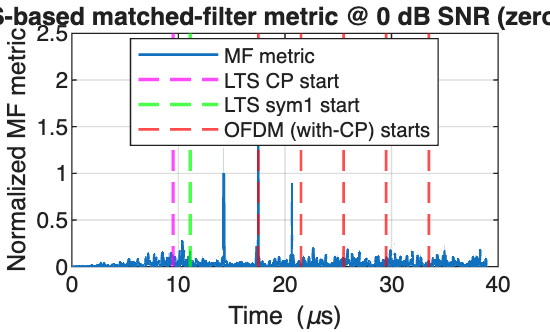

%9
sync9 = sync_by_lts(rx_noisy, lts_td, Nfft, Lcp);

% plot the match filter
t_metric_us = (0:numel(sync9.metric)-1)/Fs * 1e6;
figure; hold on; grid on; box on;
plot(t_metric_us, sync9.metric, 'LineWidth', 1.1);
xlabel('Time (\mus)'); ylabel('Normalized MF metric');
title('2-9: LTS-based matched-filter metric @ 0 dB SNR (zero-padded)');

% mark the start of STS, LTS, and 5 OFDM
yl = ylim;
xline((sync9.idx_lts_cp_start-1)/Fs*1e6,   '--m', 'LineWidth', 1.3); % LTS CP start
xline((sync9.idx_lts_sym1_start-1)/Fs*1e6, '--g', 'LineWidth', 1.3); % LTS sym1 start (no CP)
for k = 1:numel(sync9.idx_data_cp_start)
    xline((sync9.idx_data_cp_start(k)-1)/Fs*1e6, '--r', 'LineWidth', 1.0);
end
legend('MF metric','LTS CP start','LTS sym1 start','OFDM (with-CP) starts','Location','best');


% check the correctness
idx_expected_lts_cp = padN + 160 + 1;   % = 191
hit_ok = (sync9.idx_lts_cp_start == idx_expected_lts_cp);

fprintf('[2-9] Detected LTS CP start = %d (expected %d) → %s\n', ...
        sync9.idx_lts_cp_start, idx_expected_lts_cp, string(hit_ok));

[2-9] Detected LTS CP start = 191 (expected 191) → true


fprintf('[2-9] Detected LTS sym1 start (no CP) = %d\n', sync9.idx_lts_sym1_start);

[2-9] Detected LTS sym1 start (no CP) = 223


fprintf('[2-9] Detected OFDM (with-CP) starts = %s\n', mat2str(sync9.idx_data_cp_start.'));

[2-9] Detected OFDM (with-CP) starts = [351 431 511 591 671]


%10

observe:

STS-based MF (2-7):

- The metric shows periodic peaks around the STS region because STS is highly periodic.

- The main peak is broader and the peak-to-sidelobe ratio is lower.

LTS-based MF (2-9):

- A single, sharp dominant peak with lower sidelobes—a higher peak-to-sidelobe ratio.

- The largest peak appears at the first OFDM (with-CP) start. This is expected: the matched filter peaks when the template's end aligns, and that alignment occurs at the end of the LTS block, i.e., the OFDM start.

- Only the first dominant peak is a true timing lock (template matches LTS). The later peaks come from mismatch cross-correlation with the repeated CP+data pattern, and the 128 ≠ 80 length mismatch, so they don't line up with the OFDM lines.

Why:

- STS's periodicity produces multiple autocorrelation sidelobes and a wider main lobe under noise. LTS spans most subcarriers with BPSK and two consecutive 64-sample symbols; its autocorrelation has a narrow main lobe and small sidelobes. Hence LTS-MF gives a cleaner, more decisive timing metric and is more reliable at low SNR, while STS-MF is also correct but less sharp.

## Channel estimation and equalization for a multipath channel

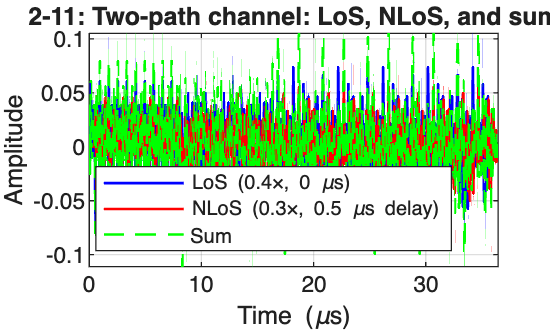

%11
x = frame_td(:);                 % 720×1
Ts_us = 1e6/Fs;                  % 0.05 us
D = round(0.5 / Ts_us);          % 0.5 us → 10 samples (exact for Fs=20 MHz)

% LoS: gain 0.4, delay = 0
x_los  = 0.4 * [x; zeros(D,1)];      % pad tail so sums align

% NLoS: gain 0.3, delay = 0.5 us (D samples)
x_nlos = 0.3 * [zeros(D,1); x];

% Received (noiseless sum)
y_rx = x_los + x_nlos;               % length = length(x)+D

% Time axis in microseconds
t_us = (0:length(y_rx)-1)/Fs * 1e6;

% Plot (time domain, real part)
figure; hold on; grid on; box on;
plot(t_us, real(x_los),'b-'  ,'LineWidth', 1.0);
plot(t_us, real(x_nlos),'r-' ,'LineWidth', 1.0);
plot(t_us, real(y_rx),'g--'   ,'LineWidth', 1.0);
xlabel('Time (\mus)'); ylabel('Amplitude');

title('2-11: Two-path channel: LoS, NLoS, and sum');
legend('LoS (0.4×, 0 \mus)','NLoS (0.3×, 0.5 \mus delay)','Sum','Location','best');
xlim([t_us(1) t_us(end)]);

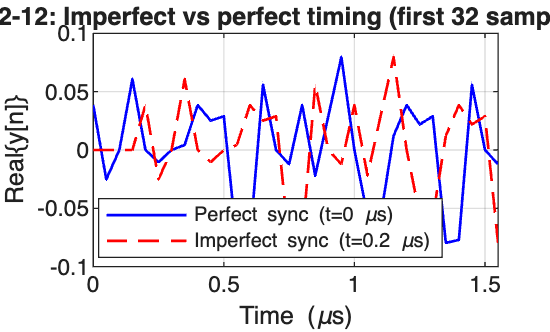

%12
Dsync   = round(0.2 / Ts_us);   % 0.2 us → 4 samples

% first 32 point of perfect synchronization
y_perfect_32 = y_rx(1:32);
t_us = (0:31) * Ts_us;                  % 0, 0.05, ..., 1.55 μs

% first 32 point of imperfect synchronization
y_imperf_32 = [zeros(Dsync,1); y_rx(1:32 - Dsync)];

% plot
figure; hold on; grid on; box on;
plot(t_us, real(y_perfect_32), 'b-', 'LineWidth', 1.0);
plot(t_us,  real(y_imperf_32),  'r--', 'LineWidth', 1.0);

xlabel('Time (\mus)'); ylabel('Real\{y[n]\}');
title('2-12: Imperfect vs perfect timing (first 32 samples)');
legend('Perfect sync (t=0 \mus)','Imperfect sync (t=0.2 \mus)','Location','best');

The perfect synchronization(blue) starts from t = 0 μs and the imperfect synchronization(red) starts forom t = 0.2 μs. Two waveform are identical except for the time shift, showing that the delay of 4 samples are correctly implemented.

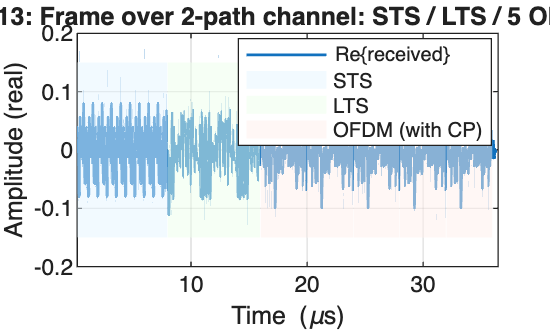

%13
rx_imp = y_rx(1 + Dsync : end);
sync13 = sync_by_lts(rx_imp, lts_td, Nfft, Lcp);

span = Nfft + Lcp;   % 80
n_sts = 160; 
nLTS  = 160;
ofs   = Dsync;       % samples trimmed from the front (to map back to original coords)
Ts_us = 1e6/Fs;

% indices in rx_imp (detection domain)
idx_lts_start_imp = sync13.idx_lts_cp_start;       % in rx_imp coords
idx_lts_end_imp   = idx_lts_start_imp + nLTS - 1;

idx_sts_end_imp   = idx_lts_start_imp - 1;
idx_sts_start_imp = max(1, idx_sts_end_imp - (n_sts - 1));   % may be shorter in rx_imp

idx_data_cp_start_imp = sync13.idx_data_cp_start(:);
idx_data_cp_end_imp   = idx_data_cp_start_imp + span - 1;

% map to ORIGINAL frame coordinates (add ofs)
idx_lts_start = idx_lts_start_imp + ofs;
idx_lts_end   = idx_lts_end_imp   + ofs;

idx_sts_start = (idx_lts_start_imp - n_sts) + ofs;   % = 161-160+ofs = 1+ofs → 1 when ofs=0
idx_sts_end   = (idx_lts_start_imp - 1)     + ofs;   % = 160+ofs

idx_data_cp_start = idx_data_cp_start_imp + ofs;
idx_data_cp_end   = idx_data_cp_end_imp   + ofs;

% plot signal (still rx_imp), but shift patches in time by ofs ----
t_us_imp = (0:length(rx_imp)-1)/Fs * 1e6;
t_shift  = ofs * Ts_us;  % time shift in microseconds

figure; hold on; grid on; box on;
plot(t_us_imp, real(rx_imp), 'LineWidth', 1.0);
xlabel('Time (\mus)'); ylabel('Amplitude (real)');
title('2-13: Frame over 2-path channel: STS / LTS / 5 OFDM');

yl = ylim;

% STS patch
xs = t_us_imp(max(1, idx_sts_start_imp)) + t_shift;
xe = t_us_imp(min(length(rx_imp), idx_sts_end_imp)) + t_shift;
if xs <= xe
    patch([xs xe xe xs], [yl(1) yl(1) yl(2) yl(2)], [0.90 0.96 1.00], ...
          'EdgeColor','none','FaceAlpha',0.5);
end

% LTS patch
xs = t_us_imp(idx_lts_start_imp) + t_shift;
xe = t_us_imp(min(length(rx_imp), idx_lts_end_imp)) + t_shift;
patch([xs xe xe xs], [yl(1) yl(1) yl(2) yl(2)], [0.93 1.00 0.92], ...
      'EdgeColor','none','FaceAlpha',0.5);

% OFDM patches
for i = 1:numel(idx_data_cp_start_imp)
    xs = t_us_imp(idx_data_cp_start_imp(i)) + t_shift;
    xe = t_us_imp(min(length(rx_imp), idx_data_cp_end_imp(i))) + t_shift;
    patch([xs xe xe xs], [yl(1) yl(1) yl(2) yl(2)], [1.00 0.94 0.92], ...
          'EdgeColor','none','FaceAlpha',0.5);
end


legend('Re\{received\}','STS','LTS','OFDM (with CP)','Location','best');
xlim([t_us_imp(1)+t_shift, t_us_imp(end)+t_shift]);

[2-13] STS:  [1, 160]


[2-13] LTS:  [161, 320]


% ---- print ORIGINAL coordinates ----

[2-13] OFDM (with-CP) starts: [321 401 481 561 641]


fprintf('[2-13] STS:  [%d, %d]\n', idx_sts_start, idx_sts_end);
fprintf('[2-13] LTS:  [%d, %d]\n', idx_lts_start, idx_lts_end);
fprintf('[2-13] OFDM (with-CP) starts: %s\n', mat2str(idx_data_cp_start.'));

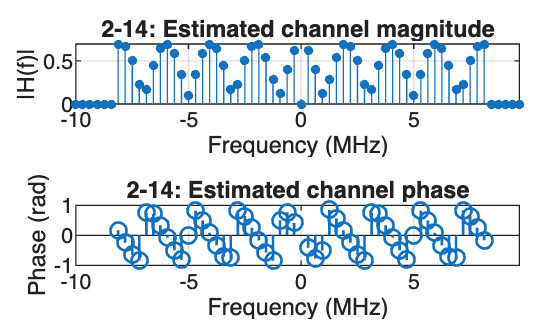

%14
idx0    = sync13.idx_lts_cp_start;                 % LTS CP start in rx_imp
lts1_td = rx_imp(idx0 + 32 : idx0 + 32 + 64 - 1);  % LTS 1
lts2_td = rx_imp(idx0 + 32 + 64 : idx0 + 32 + 64 + 64 - 1);

Y1 = fftshift(fft(lts1_td, Nfft));
Y2 = fftshift(fft(lts2_td, Nfft));
Y  = 0.5*(Y1 + Y2);                                 % RX-LTS (avg)

% Build the exact TX-LTS reference used in *this* frame
if exist('lts_td_aligned','var')
    lts_ref_td = lts_td_aligned(:);
else
    lts_ref_td = lts_td(:);
end
x1_ref = lts_ref_td(32+1 : 32+64);
x2_ref = lts_ref_td(32+64+1 : 32+64+64);
X1_ref = fftshift(fft(x1_ref, Nfft));
X2_ref = fftshift(fft(x2_ref, Nfft));
X_ref  = 0.5*(X1_ref + X2_ref);                     % TX-LTS in freq

% CE only on nonzero (active) tones; guard/DC remain 0 (not NaN)
H_est  = zeros(Nfft,1);
nz     = find(abs(X_ref) > 1e-12);
H_est(nz) = Y(nz) ./ X_ref(nz);

% tiny guard for near-zero magnitudes on active tones
tiny = 1e-12;
H_est(abs(H_est)<tiny & abs(X_ref)>0) = tiny * exp(1j*angle(H_est(abs(H_est)<tiny & abs(X_ref)>0)));
idx_active = arrayfun(toIdx, k_active);

% Plot
df   = Fs/Nfft;
k_all = (-Nfft/2):(Nfft/2-1);
f_MHz = (k_all * df) / 1e6;

figure; tiledlayout(2,1,'Padding','compact','TileSpacing','compact');
nexttile; hold on; grid on; box on;
stem(f_MHz, abs(H_est), 'filled', 'MarkerSize', 3);
xlabel('Frequency (MHz)'); ylabel('|H(f)|');
title('2-14: Estimated channel magnitude'); xlim([min(f_MHz) max(f_MHz)]);

phi = nan(size(H_est));
phi(idx_active) = unwrap(angle(H_est(idx_active)));
nexttile; hold on; grid on; box on;

stem(f_MHz, phi, 'LineWidth', 1.0);
xlabel('Frequency (MHz)'); ylabel('Phase (rad)');
title('2-14: Estimated channel phase'); xlim([min(f_MHz) max(f_MHz)]);

%15

Magnitude: a clear sinusoidal ripple across subcarriers, swinging roughly from ≈ 0.1 to ≈ 0.7. This matches the two-path model ${H\left(f\right)=0\ldotp 4+0\ldotp 3e}^{-\textrm{j2}\pi f\tau }$ with τ=0.5 μs.

- ${\left|H\left(f\right)\right|}^2 =0\ldotp 42+0\ldotp 32+2\left(0\ldotp 4\right)\left(0\ldotp 3\right)\textrm{cos }\left(2\pi f\tau \right)=0\ldotp 25+0\ldotp 24\textrm{cos }\left(2\pi f\tau \right)$, so $\left|H\left(f\right)\right|\in \left\lbrack 0\ldotp 25-0\ldotp 24,0\ldotp 25+0\ldotp 24\right\rbrack =\left\lbrack 0\ldotp 1,0\ldotp 7\right\rbrack$.

- The period of the ripple is $\Delta f=1/\tau =2\Delta f=1/\tau =2\textrm{MHz}$, with a 312.5 kHz subcarrier spacing, is about 6–7 subcarriers per cycle, which is same as the pattern.

Phase: a monotonic increase with stairs every 2 MHz.

- As frequency increases, the delayed path contributes a rotating phasor $0\ldotp 3e^{-\textrm{j2}\pi f\tau }$; adding it to the LOS phasor 0.4 makes the angle sweep with f. Near the destructive-interference frequencies (where the magnitude dips toward 0.1), the resultant vector passes close to the origin, causing rapid phase transitions (the stairs).

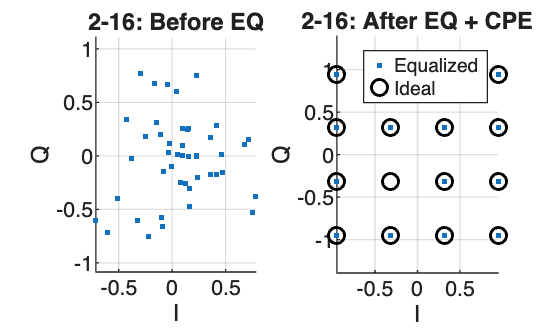

%16
idx_data  = arrayfun(toIdx, data_k);          % 48 data tones
idx_pilot = arrayfun(toIdx, pilot_idx_k);     % 4 pilot tones

rx_data_all = [];   % raw (before EQ) data tones
eq_data_all = [];   % equalized (+CPE) data tones

X_data_ref_full = fftshift(fft(x_cp(Lcp+1:end), Nfft));   % CP removed → FFT
pilot_ref = X_data_ref_full(idx_pilot);                   % TX pilots (±1)

for m = 1:numel(sync13.idx_data_cp_start)
    n0  = sync13.idx_data_cp_start(m) + Lcp;              % FFT window start
    seg = rx_imp(n0 : n0+Nfft-1);
    Xrx = fftshift(fft(seg, Nfft));                       % RX (DC-centered)

    % ZF EQ only on active tones
    Xeq = Xrx; 
    act = arrayfun(toIdx, k_active);
    Xeq(act) = Xrx(act) ./ H_est(act);

    % estimation
    pilot_eq  = Xeq(idx_pilot);
    cpe = angle(sum(conj(pilot_ref) .* pilot_eq));

    % rotate back
    Xeq_cpe = Xeq * exp(-1j * cpe);

    % equalization
    rx_data_all = [rx_data_all; Xrx(idx_data)];      %#ok<AGROW>
    eq_data_all = [eq_data_all; Xeq_cpe(idx_data)];  %#ok<AGROW>
end

% Constellation plots
ideal_const = qammod((0:15).',16,'gray','UnitAveragePower',true);
figure;
subplot(1,2,1); hold on; grid on; axis equal;
plot(real(rx_data_all), imag(rx_data_all), '.', 'MarkerSize', 6);
title('2-16: Before EQ'); xlabel('I'); ylabel('Q');


subplot(1,2,2); hold on; grid on; axis equal;
plot(real(eq_data_all), imag(eq_data_all), '.', 'MarkerSize', 6);
plot(real(ideal_const),  imag(ideal_const), 'ok', 'LineWidth', 1.1, 'MarkerSize', 6);
title('2-16: After EQ + CPE'); xlabel('I'); ylabel('Q'); legend('Equalized','Ideal');

%17
bits_per_sym = 4;
idx_data     = arrayfun(toIdx, data_k);

% tx reference
X_data_ref_full = fftshift(fft(x_cp(Lcp+1:end), Nfft));
tx_sym_idx_ref  = qamdemod(X_data_ref_full(idx_data), 16, 'gray','UnitAveragePower', true);
tx_bits_ref     = de2bi(tx_sym_idx_ref, bits_per_sym, 'left-msb');

% equalization, then demod
rx_sym_idx_eq = qamdemod(eq_data_all, 16, 'gray','UnitAveragePower', true);
rx_bits_eq    = de2bi(rx_sym_idx_eq, bits_per_sym, 'left-msb');

Nofdm       = numel(sync13.idx_data_cp_start);    % = 5

[2-17] Bit errors = 0 / 960


tx_bits_all = repmat(tx_bits_ref, Nofdm, 1);

bit_err = sum(rx_bits_eq(:) ~= tx_bits_all(:));
fprintf('[2-17] Bit errors = %d / %d\n', bit_err, numel(tx_bits_all));